# Simulation von isotropen EPR Spektren 

# mit EasySpin

Um EasySpin zu verwenden muss EasySpin installiert und die Bibliothek von EasySpin in dem Path von Matlab geladen werden!

clear, clf, clc;                     % löscht alle vorherigen Eingaben
Filename='TPOA_EPR_Spektrum';        % Filename des EPR Spektrums 
[B,ExpSpectrum, Param]=eprload('test.DSC');  % lädt den Feldvektor das experimentelle Spektrum und die Parameter

Die verschiedenen Radikale haben verschiedene Zusammensetzungen und damit unterscheidliche Hyperfeinkopplungskonstanten (HFK), Zahl der äquivalenten Kerne. Die Radikale haben natürlich auch verschiedene Linienbreiten. Diese Paramenter werden von ihnen eingesetzt.

Sys.g = 2.00678; % der isotrope g-Faktor

Easyspin erwartet die HFKs in MHz Einheiten, dazu gibt es eine Umrechnungsfunktion: mt2mhz, mT (milli Tesla) zu MHz Umrechnung. Das Spektrometer (SpinFit) rechnete alles in Gauss (=10mT)

Sys.A = mt2mhz([1.55256]); % für jede HFK ein Wert in Gauss
Sys.Nucs = '14N';     % das Isotop des Kerns passend zu jeder HFK
Sys.n = [1];            % Zahl der Äquivalenten Kerne zu jeder HFK

Die Linienbreite ist im allgemeinen eine Mischung aus Gauss- und Lorentz-Form

SpinFit hat dies in die beiden Zahlen dividiert Verhältnis (L/G) und Linienbreite die kann umgerechnet werden, z.B.:

Spin-Fit wurde L/G angegeben: 0 Lorentzian: 1 Gaussian :  d.h.: 

                  Sys.lw = [1-L/G L/G] * Linienbreite / 10

Sys.lw=[0.151];   % mixture of Lorentzian and Gaussian linewidth in mT

 Die Experimentellen Parameter werden für die Simulation verwendet:

Exp.mwFreq = Param.MWFQ / 1e9; % MW-Frequenz aus Experiment Parametern
Exp.Range = [Param.XMIN Param.XMIN+Param.XWID] / 10; %Param Field in Units of Gauss, easyspin expectes mT
Exp.nPoints = Param.XPTS; % die Anzahl der Punkte im Spektrum

Das Experimentelle Spektrum wird Baseline-Korrigert und auf +/-1 Normiert

% Spektrum maximum und minimum finden
imax = max(ExpSpectrum); imin = min(ExpSpectrum); 
% Baseline aus ersten 100 Punkten
imean = mean(ExpSpectrum(1:100));
% Spektrum auf -1 bis +1 'normieren'
ExpSpectrum = (ExpSpectrum-imean) / (imax-imin) * 2 ;

Jetzt wird das cw-EPR Spektrum mit den gegebenen Spin-Hamilton-Parametern simuliert und mit dem experimentellen Spektrum verglichen:

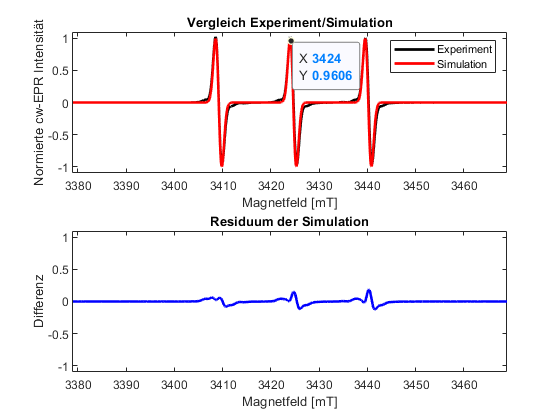

SimSpectrum = garlic(Sys,Exp);     % für fast motion cw-EPR Spektren
SimSpectrum=SimSpectrum/max(SimSpectrum); % Normierung auf +/- 1
SimSpectrum=SimSpectrum';   % Von Zeilen zu Spaltenvektor
subplot(211)
plot(B,ExpSpectrum,'k',B,SimSpectrum,'r','LineWidth',2);
axis tight
legend('Experiment', 'Simulation');  % Beschriftung
xlabel('Magnetfeld [mT]','FontSize',15);
ylabel('Normierte cw-EPR Intensität','FontSize',15);
ylim([-1.1 1.1]);
title('Vergleich Experiment/Simulation');
subplot(212);
plot(B,ExpSpectrum-SimSpectrum,'b','LineWidth',2);
axis tight;
xlabel('Magnetfeld [mT]','FontSize',15);
ylabel('Differenz','FontSize',15);
ylim([-1.1 1.1]);
title('Residuum der Simulation');